A = [0 1 0;0 0 1;-6 -11 -6];
b = [1;1;0];
c = [1 0 1];
d = 0;
sys = ss(A,b,c,d);

% modal canonical form
V = sym([1 1 1;-1 -2 -3;1 4 9]);
T = inv(V)

$$T = \left(\begin{array}{ccc} 3 & \frac{5}{2} & \frac{1}{2}\\ -3 & -4 & -1\\ 1 & \frac{3}{2} & \frac{1}{2} \end{array}\right)$$

T*A*inv(T)

$$ans = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & -2 & 0\\ 0 & 0 & -3 \end{array}\right)$$

T*b

$$ans = \left(\begin{array}{c} \frac{11}{2}\\ -7\\ \frac{5}{2} \end{array}\right)$$

Q = sym(diag([2/11 -1/7 2/5]));
% combine the transformations:
P = Q*T;
A1 = P*A*inv(P)

$$A1 = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & -2 & 0\\ 0 & 0 & -3 \end{array}\right)$$

b1 = P*b

$$b1 = \left(\begin{array}{c} 1\\ 1\\ 1 \end{array}\right)$$

c1 = c*inv(P)

$$c1 = \left(\begin{array}{ccc} 11 & -35 & 25 \end{array}\right)$$

sys_modal = ss2ss(sys, double(P));
% do some cleanup
sys_modal.A(abs(sys_modal.A) < 1e-14) = 0;
sys_modal.C(abs(sys_modal.C) < 1e-14) = 0;
sys_modal

sys_modal =
 
  A = 
       x1  x2  x3
   x1  -1   0   0
   x2   0  -2   0
   x3   0   0  -3
 
  B = 
       u1
   x1   1
   x2   1
   x3   1
 
  C = 
        x1   x2   x3
   y1   11  -35   25
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



cm = ctrb(sys)

cm =      1     1     0
     1     0   -17
     0   -17    96


rank(cm)

ans = 3

om = obsv(sys)

om =      1     0     1
    -6   -10    -6
    36    60    26


rank(om)

ans = 3

G = tf(sys)

G =
 
     s^2 - 10 s + 11
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.



pole(G)

ans =    -3.0000
   -2.0000
   -1.0000


zero(G)

ans =     8.7417
    1.2583


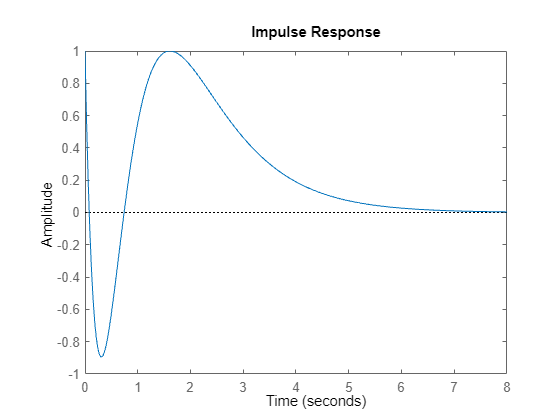

impulse(G)

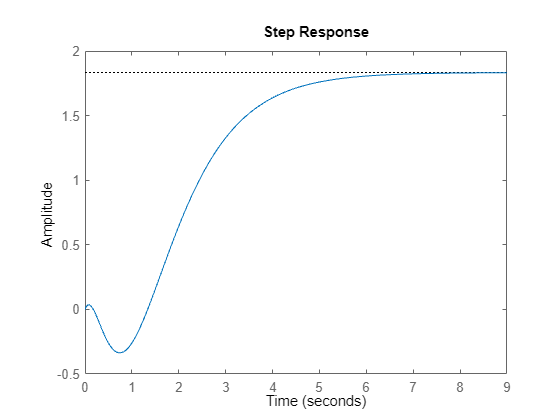

step(G)

syms s
adj = adjoint(s*eye(3) - A)

$$adj = \left(\begin{array}{ccc} s^{2}+6\,s+11 & s+6 & 1\\ -6 & s^{2}+6\,s & s\\ -6\,s & -11\,s-6 & s^{2} \end{array}\right)$$

det(s*eye(3) - A)

$$ans = s^{3}+6\,s^{2}+11\,s+6$$

c*adj*b

$$ans = s^{2}-10\,s+11$$